clear
addpath("frffit"); addpath("Assignments"); addpath("Assignment 3")



syms s m1 m2 k d 
lambda = (m1*s^2 + d*s + k) * (m2*s^2 + d*s + k)

$$lambda = \left(m_{1}\,s^{2}+d\,s+k\right)\,\left(m_{2}\,s^{2}+d\,s+k\right)$$

H1 = (m2*s^2 + d*s +k) / ( lambda -(k + d*s)^2 )

$$H1 = -\frac{m_{2}\,s^{2}+d\,s+k}{{\left(k+d\,s\right)}^{2}-\left(m_{1}\,s^{2}+d\,s+k\right)\,\left(m_{2}\,s^{2}+d\,s+k\right)}$$

H1 = collect(H1)

$$H1 = \frac{m_{2}\,s^{2}+d\,s+k}{\left(m_{1}\,m_{2}\right)\,s^{4}+\left(d\,m_{1}+d\,m_{2}\right)\,s^{3}+\left(k\,m_{1}+k\,m_{2}\right)\,s^{2}}$$


b = k + d*s

$$b = k+d\,s$$

H2 = (b/lambda)/(1 - b^2/lambda)

$$H2 = -\frac{k+d\,s}{\left(\frac{{\left(k+d\,s\right)}^{2}}{\left(m_{1}\,s^{2}+d\,s+k\right)\,\left(m_{2}\,s^{2}+d\,s+k\right)}-1\right)\,\left(m_{1}\,s^{2}+d\,s+k\right)\,\left(m_{2}\,s^{2}+d\,s+k\right)}$$

H2 = simplify(H2)

$$H2 = \frac{k+d\,s}{s^{2}\,\left(k\,m_{1}+k\,m_{2}+m_{1}\,m_{2}\,s^{2}+d\,m_{1}\,s+d\,m_{2}\,s\right)}$$

H2 = collect(H2)

$$H2 = \frac{d\,s+k}{\left(m_{1}\,m_{2}\right)\,s^{4}+\left(d\,m_{1}+d\,m_{2}\right)\,s^{3}+\left(k\,m_{1}+k\,m_{2}\right)\,s^{2}}$$


m1 = 0.015; %[kg]
m2 = 0.045; %[kg]
d = 0.4;    %[Ns/m]
k = 2200;   %[N/m]

%manually type over transfer function
H1 = tf([m2,d,k],[m1*m2,d*m1+d*m2,k*m1+k*m2,0,0]) 

H1 =
 
       0.045 s^2 + 0.4 s + 2200
  ----------------------------------
  0.000675 s^4 + 0.024 s^3 + 132 s^2
 
Continuous-time transfer function.
Model Properties


H2 = tf([d,k],[m1*m2,d*m1+d*m2,k*m1+k*m2,0,0])

H2 =
 
             0.4 s + 2200
  ----------------------------------
  0.000675 s^4 + 0.024 s^3 + 132 s^2
 
Continuous-time transfer function.
Model Properties


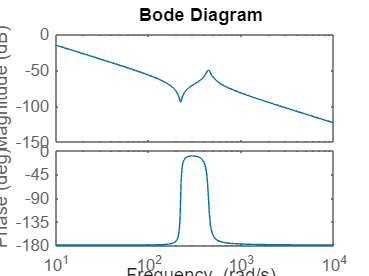

bode(H1)

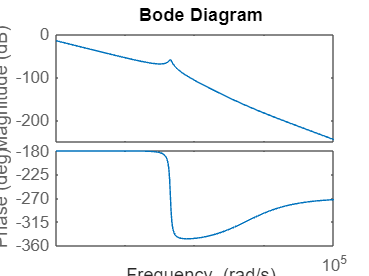

bode(H2)